# ECE 585 HW 4

## Problem 1 Support

mag_s = (norminv(1-1e-3) - norminv(1-.9))^2

mag_s = 19.1125


norm([1,2,3,4])^2

ans = 30

### Problem 2

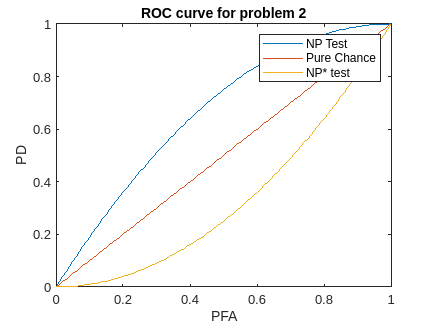

clf;

%plot NP test line
PFA = 0:0.01:1;
PD = PFA .* (2 - PFA);
plot(PFA,PD,"DisplayName","NP Test")
hold on

%plot pure chance line
plot(0:0.01:1,0:0.01:1, "DisplayName","Pure Chance")

%plot conjugate NP test line
PD_conj = 1 - 2 .* (1 - PFA) + (1 - PFA).^(2);
plot(PFA,PD_conj,"DisplayName","NP* test")

%define labels
xlabel("PFA")
ylabel("PD")
title("ROC curve for problem 2")
legend

## Problem 3

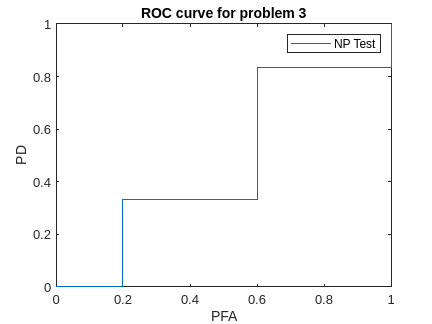

clf;
% plot NP test line
PFA = [0,1/5,3/5,1];
PD = [0,1/3,5/6,1];
%stem(PFA,PD,"DisplayName","NP Test")
stairs(PFA,PD,"DisplayName","NP Test")
hold on

%plot pure chance line
% plot(0:0.01:1,0:0.01:1, "DisplayName","Pure Chance")

%define labels
xlabel("PFA")
ylabel("PD")
title("ROC curve for problem 3")
legend